# Lab Assignment 3

First, we will see how eigenvalues and vectors can be used to find the principal components of a dataset. To understand PCA we need to understand the following statistical terms: *standard deviation, variance and mariance*.

- ***Sample Standard Deviation (SD)*** is a measure of the deviation from the mean of the data set to a point. The way to calculate it is to compute the squares of the distance from each data point to the mean of the set, add them all up, divide by *n-1*, and take the positive square root.


$$\mathit{\mathbf{s}}=\sqrt{\;\frac{\sum_{\mathit{\mathbf{i}}=1}^{\mathit{\mathbf{n}}} {\left({\mathit{\mathbf{X}}}_{\mathit{\mathbf{i}}\;} -\bar{\mathit{\mathbf{X}}} \right)}^2 }{\mathit{\mathbf{n}}-1}}$$
  

- ***Sample Variance (V): ***Variance is another measure of the spread of data in a data set. In fact it is the square of the standard deviation. The formula is this:

 
$${\mathit{\mathbf{s}}}^2 =$$
 
$$\frac{\sum_{\mathit{\mathbf{i}}=1}^{\mathit{\mathbf{n}}} {\left({\mathit{\mathbf{X}}}_{\mathit{\mathbf{i}}\;} -\bar{\mathit{\mathbf{X}}} \right)}^2 }{\mathit{\mathbf{n}}-1}$$


- ***Sample Covariance (C):*** Standard deviation and variance only operate on 1 dimension, so that you could only calculate the standard deviation for each dimension of the data set independently of the other dimensions. However, it is useful to have a similar measure to find out how much the dimensions vary from the mean with respect to each other. Covariance is such a measure. Covariance is always measured between 2 dimensions. If you calculate the covariance between one dimension and itself, you get the variance. So, if you had a 3-dimensional data set (*x,y,z*), then you could measure the covariance between the *x* and *y* dimensions, the *x *and *z* dimensions, and the *y* and *z* dimensions. Measuring the covariance between *x *and *x*, or *y *and *y*, or *z *and *z* would give you the variance of the *x*, *y* and *z* dimensions respectively.


$$\textrm{Cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)=$$
 
$$\frac{\sum_{\mathit{\mathbf{i}}=1}^{\mathit{\mathbf{n}}} {\left({\mathit{\mathbf{X}}}_{\mathit{\mathbf{i}}\;} -\bar{\mathit{\mathbf{X}}} \right)\left({\mathit{\mathbf{Y}}}_{\mathit{\mathbf{i}}} -\bar{\mathit{\mathbf{Y}}} \right)} }{\mathit{\mathbf{n}}-1}$$


- The covariance matrix shows the relationship between different features(i.e. columns) in the dataset. For a three dimentional dataset the covariance matrix would look something like this:


$$\textrm{Cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}},\mathit{\mathbf{z}}\right)\left\lbrack \begin{array}{c}
\textrm{cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{x}}\right)\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{z}}\right)\\
\textrm{cov}\left(\mathit{\mathbf{y}},\mathit{\mathbf{x}}\right)\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{y}},\mathit{\mathbf{y}}\right)\;\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{y}},\mathit{\mathbf{z}}\right)\\
\textrm{cov}\left(\mathit{\mathbf{z}},\mathit{\mathbf{x}}\right)\;\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{z}},\mathit{\mathbf{y}}\right)\;\;\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{z}},\mathit{\mathbf{z}}\right)
\end{array}\right\rbrack$$


- If the value is positive, then that indicates that both dimensions increase together. If the value is negative, then as one dimension increases, the other decreases. In the last case, if the covariance is zero, it indicates that the two dimensions are independent of each other.

## **Exercise 1: Eigenvalues and Eigenvectors**

- The eigenvalues and vectors describe the essense of how a matrix transforms a vector. To see the effect we can generate a set of vectors of unit length representing all directions:

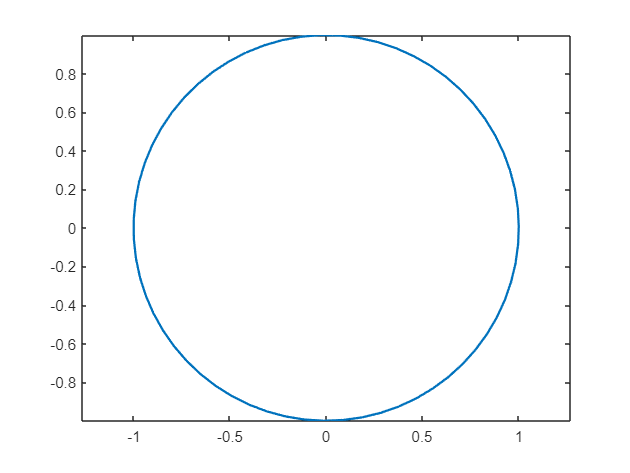

t = 0:0.1:2*pi+0.1;
x = [cos(t); sin(t)];
plot(x(1,:),x(2,:),'LineWidth',1.5)
axis equal

- Let's Transform the vectors using some matrix A and see how it effects the vectors:

A = [1 .2
     .2 1];
y = A*x

y =     1.0000    1.0150    1.0198    1.0144    0.9989    0.9735    0.9383    0.8937    0.8402    0.7783    0.7086    0.6318    0.5488    0.4602    0.3671    0.2702    0.1707    0.0695   -0.0324   -0.1340   -0.2343   -0.3322   -0.4268   -0.5171   -0.6023   -0.6814   -0.7538   -0.8186   -0.8752   -0.9231   -0.9618   -0.9908   -1.0100   -1.0190   -1.0179   -1.0066   -0.9853   -0.9541   -0.9133   -0.8635   -0.8050   -0.7385   -0.6646   -0.5840   -0.4977   -0.4063   -0.3109   -0.2124   -0.1117   -0.0100
    0.2000    0.2988    0.3947    0.4866    0.5736    0.6549    0.7297    0.7972    0.8567    0.9076    0.9495    0.9819    1.0045    1.0171    1.0194    1.0116    0.9937    0.9659    0.9284    0.8816    0.8261    0.7622    0.6908    0.6125    0.5280    0.4382    0.3441    0.2466    0.1465    0.0451   -0.0569   -0.1582   -0.2580   -0.3552   -0.4489   -0.5381   -0.6219   -0.6995   -0.7701   -0.8330   -0.8875   -0.9332   -0.9696   -0.9963   -1.0131   -1.0197   -1.0161   -1.0024   -0.9787   -0

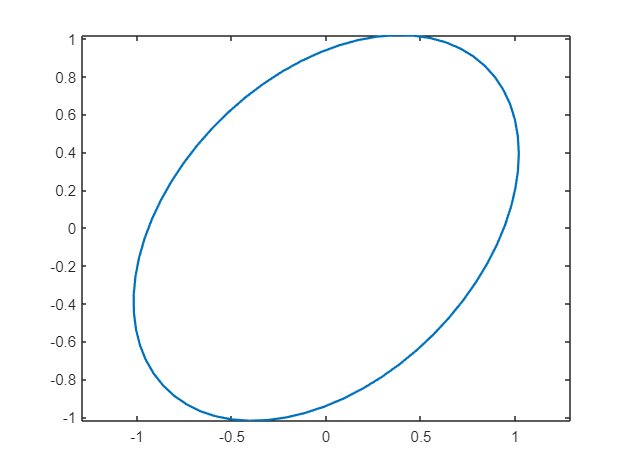

plot(y(1,:),y(2,:),'LineWidth',1.5)
axis equal

- Using the eigenvectors and values we can compactly capture the effect of the matrix, and draw the transform. The transform here means the direction in which the vectors were affected the most. You can plot the major and minor axis of this ellipse to visualize the magnitude of change.

[X,D] = eig(A)

X =    -0.7071    0.7071
    0.7071    0.7071


D =     0.8000         0
         0    1.2000


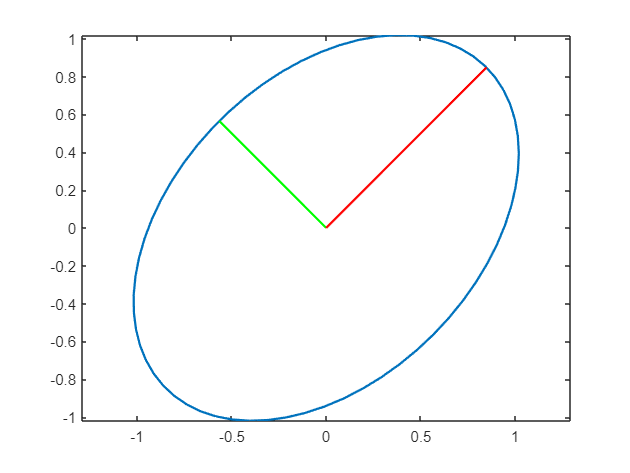

plot(y(1,:),y(2,:),'LineWidth',1.5)
axis equal
hold on
plot(D(1,1)*[0 X(1,1)],D(1,1)*[0 X(2,1)],'g','LineWidth',1.5)
plot(D(2,2)*[0 X(1,2)],D(2,2)*[0 X(2,2)],'r','LineWidth',1.5)
hold off

- Try a few of these transforms on your own (no need to turn in), to get an idea of the effect of different matrices. Remember that (symmetric) positive definite matrices will give you real orthonormal eigenvectors. Unsymmetric matrices may give complex results. To think about: In the above example we only rotated and scaled. More generally we can also add translation $\mathit{\mathbf{y}}=\mathit{\mathbf{A}}\ldotp \mathit{\mathbf{x}}+\mathit{\mathbf{t}}$. You might try on your own to make a routine which can plot any ellipse given its parametric form (as in Heath Computer problem 3.5). A more common problem in practice is that we have data that we want to somehow characterize. The data may have significant variation along some axis and less along others. A common model is that of a Gaussian distribution. If there is little variation along a particular axis, that dimension could be omitted altogether. 

%You can create your own Gaussian Distribution using the following code:
% Gaussian distr, Box-Mueller method
n = 400

n = 400

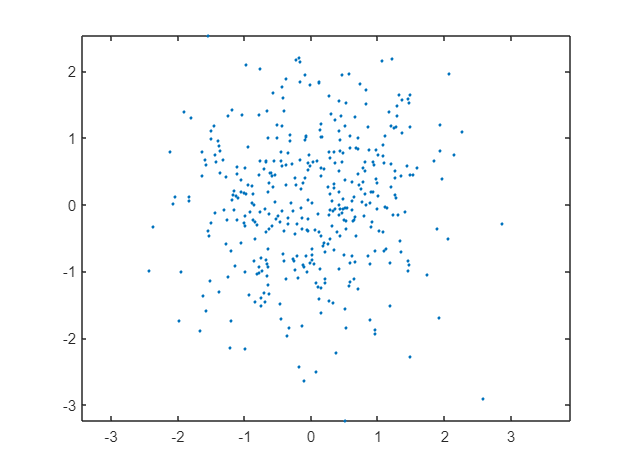

U = rand(2,n);
v = 2*pi*U(2,:);
G = ones(2,1)*sqrt(-2.*log(U(1,:))).*[cos(v);sin(v)];

plot(G(1,:),G(2,:),'.')
axis equal

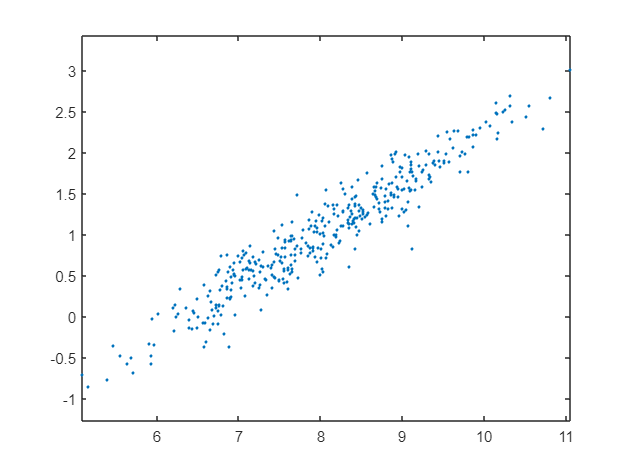


% Transform
A = [1 .5
     .5 0.5];
t = [8; 1];
Y = A*G+t*ones(1,n);
plot(Y(1,:),Y(2,:),'.')
axis equal

[X,D] = eig(A)

X =     0.5257   -0.8507
   -0.8507   -0.5257


D =     0.1910         0
         0    1.3090


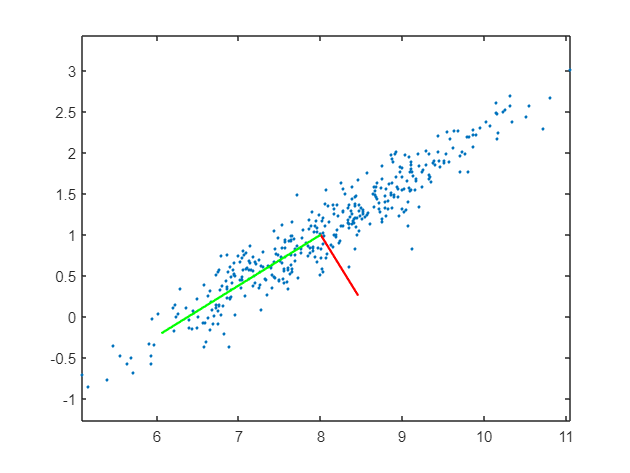

D=sqrt(D);
plot(Y(1,:),Y(2,:),'.')
axis equal
hold on
plot(2*D(1,1)*[0 X(1,1)]+8,2*D(1,1)*[0 X(2,1)]+1,'r','LineWidth',1.5)
plot(2*D(2,2)*[0 X(1,2)]+8,2*D(2,2)*[0 X(2,2)]+1,'g','LineWidth',1.5)
hold off

## Principal Componet Analysis (PCA)

Principal components are the orthogonal vectors which correspond to highest variance of the data. Eigenvalues are the variances in the direction of the corresponding eigenvector.

When using PCA we need to standardize the data by transforming it to having mean = 0. This is important because in PCA we will be looking at how different features contribute to the spread of the data. Therefore, different features must be comparable in terms of scale. Here we show how to standardize the data:


$$\textrm{For}\;\textrm{any}\;\textrm{matrix}\;{\mathit{\mathbf{A}}}_{\mathit{\mathbf{m}}\times \mathit{\mathbf{n}}}$$



$${\mathit{\mathbf{A}}}_{\textrm{std}} =\frac{\left(\mathit{\mathbf{A}}-\bar{\mathit{\mathbf{A}}} \right)}{s}$$
        


$$\textrm{Cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}$$


Here, the eigenvectors of this covariance matrix are the principal components. **Can you explain why (based on the definition of Covariance stated above)?**

- In this exercise you will use PCA as described in the [this document](https://drive.google.com/file/d/1WXEtpBKHu_ZzSUMMrmejGIsPjVALYaeI/view?usp=sharing) and below. The purpose is to recover the main axes of the distribution and plot the axes with length (2*sqrt of eigenvalues). You can plot the axes as in the Gaussian example above, or plot an ellipse corresponding to the axes.

- Three data sets Y1, Y2 and Y3 are provided in [EllipsePoints.mat](https://drive.google.com/file/d/1WdXYGlvfQ-c19tOv3efVAQ9vzqNc7Ofy/view?usp=sharing). Show how to find the major and minor axes of those.

%%%%            Enter your code here        %%%%
%Add relevant comments and answers to the questions asked
load("EllipsePoints.mat");
Y1

Y1 =    -8.5877   -7.4077   -6.9059   -9.5032   -8.0194   -8.5189   -8.6528   -8.9157   -7.9306   -9.6587   -8.3409   -8.2330   -6.8322   -7.7671   -9.4736   -6.3292   -6.8667   -7.0732   -7.2858   -7.3029   -6.5256   -8.3331   -8.0894   -8.7688   -8.3624   -9.1400   -6.3646   -7.5700   -8.8261   -9.3482   -7.3114   -7.2131   -8.5635   -9.4218   -7.5649   -8.7469   -7.6334   -8.3481   -7.8328   -8.2017   -7.8846   -7.1317   -9.0126   -8.5176   -7.5959   -8.7098   -9.8720   -8.8195   -9.0678  -10.9163
    0.2899    0.4764    1.0768   -1.1863   -1.1292    0.9042   -0.0463    0.4523   -0.5992   -0.6782   -0.1000   -0.2595    1.0506    0.4158   -1.1309    0.6751    0.6309    0.8588   -0.0545    1.2595    1.3682    0.6942   -0.9536   -1.0870   -0.9291   -0.9254    0.4421   -0.0188    0.8654   -1.4568   -0.2094    0.6442   -1.4523   -1.1338    0.1101   -0.4654    1.0597   -0.0788   -0.3258   -0.7354   -0.3226   -0.0556   -1.1933   -0.5163    0.5997   -1.1569   -1.3410   -0.6083   -1.2128   -


%%%%            End             %%%%

## **Exercise 2: A moving wave image**

The effect of image motion can be obtained by modulating a sin/cos basis. Considering the following formula:


$$\;\sin \left(\mathit{\mathbf{ax}}+\mathit{\mathbf{bt}}\right)=\sin \left(\mathit{\mathbf{ax}}\right)\cos \left(\mathit{\mathbf{bt}}\right)+\cos \left(\mathit{\mathbf{ax}}\right)\sin \left(\mathit{\mathbf{bt}}\right)$$


where a and b are constants, x is the spatial variable and t is time. We can interpret the above formula as the modulation of a sin and cos spatial basis with time varying coefficients - cos(bt), sin(bt). The example can be extended in 2D. Download the [sincos_basis.mat](https://drive.google.com/file/d/1WfeNzDTpaUEz6KQE2kgG0S5bFQiLck5l/view?usp=sharing) data. B contains the sin/cos image basis (as columns) and Y is an example set of temporal modulation coefficients (each set of coefficients is a column, hence Y(:,1) are the coefficients for time 1, Y(:,2) for time 2 etc.). Show the modulated images on the screen in quick succession resulting from the different coefficients in Y. You can use imshow, then drawnow to force immediate rendering to the screen.

You can use the function [renderim.m](https://drive.google.com/file/d/1WhsMAo1TSdSbsPx-a5gpk-TBk0KX_CCZ/view?usp=sharing) Ii = renderim(Y(:,i),B,imsize); imshow(Ii,[]); drawnow; pause(0.1);

**Why do you see the pattern moving even though it only has 1 frame? **

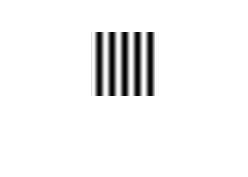


load sincos_basis.mat;
figure('visible','on')
for i=1:64
Ii=renderim(Y(:,i),B,imsize);
imshow(Ii,[]);
drawnow;
pause(0.01);
end

- Construct a similar basis that has twice the frequency of the given one and show the effect of motion through modulation.

- **What is the effect of changing b ?**

%%%%            Enter your code here            %%%%
%Add relevant comments and answers to the questions asked


%%%%            End             %%%%

## **Exercise 3: Small image motion**

Consider an image $\mathit{\mathbf{I}}=\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)$. We study the effect of a small shift (horizontal and vertical) using Taylor expansion:


$$\mathit{\mathbf{I}}\left(\mathit{\mathbf{u}}+\mathit{\mathbf{du}},\mathit{\mathbf{v}}+\mathit{\mathbf{dv}}\right)=\mathit{\mathbf{I}}\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)+\left\lbrack \mathit{\mathbf{Ix}}\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)\mathit{\mathbf{Iy}}\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)\right\rbrack \left\lbrack \mathit{\mathbf{du}}\;\mathit{\mathbf{dv}}\right\rbrack \prime +\mathit{\mathbf{hot}}$$


$\textrm{GI}=\left\lbrack \textrm{Ix}\;\textrm{Iy}\right\rbrack$ represents the image gradient. Again we can interpret the above formula using image modulation. In this case the basis B is formed by $\left\lbrack \mathit{\mathbf{I}},\;\textrm{Ix},\;\textrm{Iy}\right\rbrack$ and the coefficients are of the form $\left\lbrack 1\;\textrm{du}\;\textrm{dv}\right\rbrack$. The effect of the modulation is a small image shift. In the below we compute the derivative by taking differences in spatial coordinates. It is also possible to use a time series of images, akin to this example of a [bus](https://docs.google.com/document/d/19ONkicvWPNBcW6BZTkp7PhyiQPvqL4zpB57f1JBw9co/edit?usp=sharing).

Download the [immotion_basis.mat](https://drive.google.com/file/d/1WqAEQECjX35QumdcduaR-V7nv_BW5XYZ/view?usp=sharing) data. The data is in the same format as before. Visualize the motions produced by the given coefficients the same way as for the example above. (You can slow down the rendering speed to see the effect better by using a more finely spaced set of t-values, e.g. -3:0.2:3, appropriatetely inserted into the Y matrix of coefficients.

Repeat the procedure for another image of your choice. To calculate the image gradient (derivatives) use the Matlab function 'gradient'. Study the effect of changing the magnitudes of the coefficients in Y. What happens if you pick larger Y values (e.g. 5:10)? **Why? What type of image does this procedure work best for? Explain appealing to the Taylor expansion what happens when it doesn't work.**

%%%%            Enter your code here            %%%%
%Add relevant comments and answers to the questions asked


%%%%            End             %%%%